close all; clc; clearvars;

T = readtable("CaracteristicasDETECCION4.csv");
T_error = readtable("T_buenacalidad_revisadas_ERRORES.csv");

#### Correlation

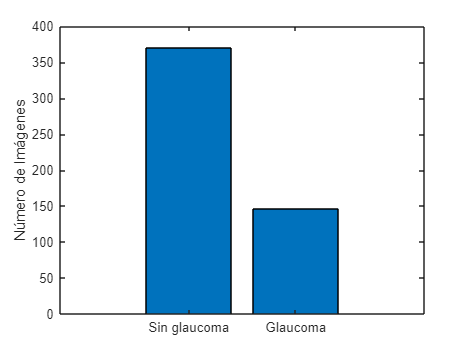

% images_with_error_SEGM = T_error.image(T_error.error_segmentacion == 1);
% % Encontrar los índices de las filas en T que tienen imágenes en images_with_error
% rows_to_remove = ismember(T.imagen, images_with_error_SEGM);
% % Eliminar las filas que deben ser eliminadas
% T(rows_to_remove, :) = [];
% 
% images_with_error_DISCO = T_error.image(T_error.error_disco == 1);
% % Encontrar los índices de las filas en T que tienen imágenes en images_with_error
% rows_to_remove = ismember(T.imagen, images_with_error_DISCO);
% % Eliminar las filas que deben ser eliminadas
% T(rows_to_remove, :) = [];
% 
% images_with_error_COPA = T_error.image(T_error.error_copa == 1);
% % Encontrar los índices de las filas en T que tienen imágenes en images_with_error
% rows_to_remove = ismember(T.imagen, images_with_error_COPA);
% % Eliminar las filas que deben ser eliminadas
% T(rows_to_remove, :) = [];
% 
% images_with_error_DISCO2 = T_error.image(T_error.error_disco2 == 1);
% % Encontrar los índices de las filas en T que tienen imágenes en images_with_error
% rows_to_remove = ismember(T.imagen, images_with_error_DISCO2);
% % Eliminar las filas que deben ser eliminadas
% T(rows_to_remove, :) = [];
% % 
% % % fotos_buenas = { 'image_0010.jpg', 'image_0016.jpg', 'image_0034.jpg', 'image_0035.jpg', 'image_0041.jpg', 'image_0044.jpg', 'image_0058.jpg', 'image_0064.jpg', 'image_0077.jpg', 'image_0079.jpg', 'image_0081.jpg', 'image_0083.jpg', 'image_0084.jpg', 'image_0085.jpg', 'image_0088.jpg', 'image_0089.jpg', 'image_0090.jpg', 'image_0093.jpg', 'image_0095.jpg', 'image_0105.jpg', 'image_0110.jpg', 'image_0124.jpg', 'image_0126.jpg','image_0128.jpg','image_0146.jpg','image_0148.jpg', 'image_0153.jpg', 'image_0154.jpg', 'image_0155.jpg', 'image_0164.jpg', 'image_0167.jpg', 'image_0169.jpg', 'image_0170.jpg', 'image_0175.jpg', 'image_0185.jpg', 'image_0189.jpg', 'image_0199.jpg', 'image_0201.jpg',  'image_0216.jpg', 'image_0224.jpg', 'image_0226.jpg', 'image_0227.jpg', 'image_0233.jpg', 'image_0234.jpg',  'image_0237.jpg', 'image_0238.jpg','image_0240.jpg', 'image_0277.jpg', 'image_0313.jpg','image_0317.jpg','image_0320.jpg','image_0321.jpg','image_0325.jpg', 'image_0326.jpg','image_0330.jpg','image_0339.jpg','image_0344.jpg','image_0346.jpg','image_0360.jpg','image_0362.jpg','image_0367.jpg','image_0369.jpg','image_0370.jpg','image_0372.jpg','image_0376.jpg','image_0377.jpg','image_0378.jpg','image_0381.jpg','image_0404.jpg'};
% % % T = T(ismember(T.imagen, fotos_buenas), :);
% % 
% % % fotos_buenas = { 'image_0010.jpg', 'image_0016.jpg','image_0027.jpg','image_0034.jpg', 'image_0035.jpg',  'image_0044.jpg','image_0048.jpg', 'image_0049.jpg', 'image_0052.jpg', 'image_0053.jpg', 'image_0055.jpg', 'image_0058.jpg', 'image_0064.jpg', 'image_0077.jpg', 'image_0079.jpg', 'image_0084.jpg', 'image_0090.jpg', 'image_0093.jpg', 'image_0095.jpg', 'image_0105.jpg', 'image_0110.jpg', 'image_0124.jpg', 'image_0126.jpg','image_0128.jpg','image_0146.jpg','image_0148.jpg'};
% % % T = T(ismember(T.imagen, fotos_buenas), :);
% % 
% % % [n, m] = size(T);
% % % for i=1:n
% % %     disco = imread(['DISCO4', T.imagen{i}]);
% % %     carpeta_DISCO = 'segmentacion_disco4_BUENAS';
% % %     mkdir(carpeta_DISCO);
% % %     
% % %     nombre_imagen = T.imagen{i};
% % %     nombre_imagen_con_disco = ['DISCO4_BUENA', nombre_imagen];
% % %     % Guardar la imagen en la carpeta
% % %     [~, nombre_sin_extension, extension] = fileparts(nombre_imagen_con_disco);
% % %     nombre_imagen_guardada = fullfile(carpeta_DISCO, [nombre_sin_extension, extension]);
% % %     imwrite(disco, nombre_imagen_guardada);
% % % end
% % 
% fotos_malas = {'image_0042.jpg', 'image_0112.jpg', 'image_0135.jpg', 'image_0137.jpg', 'image_0157.jpg', 'image_0184.jpg', 'image_0249.jpg', 'image_0269.jpg', 'image_0283.jpg', 'image_0285.jpg', 'image_0340.jpg', 'image_0354.jpg', 'image_0383.jpg', 'image_0387.jpg', 'image_0402.jpg', 'image_0494.jpg',  'image_0513.jpg', 'image_0540.jpg','image_0562.jpg','image_0580.jpg', 'image_0597.jpg', 'image_0620.jpg', 'image_0647.jpg', 'image_0705.jpg', 'image_0709.jpg',  'image_0730.jpg', 'image_0755.jpg',  'image_0778.jpg', 'image_0783.jpg', 'image_0791.jpg', 'image_0827.jpg', 'image_0841.jpg', 'image_0852.jpg', 'image_0863.jpg','image_0901.jpg', 'image_0902.jpg', 'image_0905.jpg', 'image_0918.jpg', 'image_0921.jpg', 'image_0926.jpg', 'image_0983.jpg','image_1028.jpg',  'image_1031.jpg', 'image_1061.jpg', 'image_10741.jpg', 'image_1082.jpg', 'image_1098.jpg', 'image_1103.jpg', 'image_1126.jpg', 'image_1129.jpg', 'image_1128.jpg', 'image_1163.jpg', 'image_1196.jpg', 'image_1223.jpg',  'image_1228.jpg','image_1229.jpg', 'image_1234.jpg', 'image_1234.jpg', 'image_1244.jpg', 'image_1257.jpg', 'image_1259.jpg', 'image_1268.jpg', 'image_1269.jpg', 'image_1270.jpg','image_1274.jpg','image_1318.jpg',  'image_1345.jpg', 'image_1351.jpg',  'image_1360.jpg', 'image_1356.jpg', 'image_1406.jpg', 'image_1446.jpg', 'image_1454.jpg', 'image_1455.jpg', 'image_1463.jpg','image_1466.jpg', 'image_1469.jpg', 'image_1470.jpg','image_1498.jpg',  'image_1507.jpg', 'image_1567.jpg' };
% rows_to_remove = ismember(T.imagen, fotos_malas);
% % Eliminar las filas que deben ser eliminadas
% T(rows_to_remove, :) = [];

fotos_buenas = {'image_0001.jpg','image_0003.jpg', 'image_0004.jpg','image_0007.jpg', 'image_0008.jpg','image_0009.jpg', 'image_0011.jpg','image_0015.jpg', 'image_0016.jpg','image_0018.jpg','image_0019.jpg', 'image_0020.jpg', 'image_0024.jpg', 'image_0025.jpg',  'image_0029.jpg', 'image_0030.jpg', 'image_0032.jpg',  'image_0035.jpg', 'image_0036.jpg', 'image_0039.jpg',  'image_0044.jpg','image_0047.jpg', 'image_0049.jpg', 'image_0052.jpg', 'image_0053.jpg', 'image_0058.jpg', 'image_0059.jpg', 'image_0060.jpg', 'image_0064.jpg','image_0072.jpg', 'image_0074.jpg',  'image_0077.jpg','image_0078.jpg',  'image_0079.jpg','image_0081.jpg', 'image_0082.jpg', 'image_0083.jpg',  'image_0084.jpg','image_0085.jpg', 'image_0088.jpg', 'image_0089.jpg',  'image_0090.jpg', 'image_0093.jpg', 'image_0095.jpg', 'image_0098.jpg', 'image_0105.jpg', 'image_0108.jpg', 'image_0110.jpg', 'image_0111.jpg', 'image_0112.jpg', 'image_0115.jpg','image_0119.jpg',  'image_0121.jpg', 'image_0124.jpg', 'image_0126.jpg','image_0129.jpg','image_0136.jpg', 'image_0139.jpg', 'image_0142.jpg',  'image_0144.jpg','image_0148.jpg', 'image_0153.jpg','image_0154.jpg', 'image_0155.jpg', 'image_0159.jpg', 'image_0164.jpg', 'image_0166.jpg', 'image_0167.jpg', 'image_0171.jpg','image_0172.jpg','image_0185.jpg', 'image_0189.jpg',  'image_0191.jpg', 'image_0192.jpg', 'image_0196.jpg', 'image_0199.jpg', 'image_0201.jpg', 'image_0206.jpg', 'image_0208.jpg', 'image_0209.jpg', 'image_0212.jpg', 'image_0216.jpg', 'image_0220.jpg', 'image_0222.jpg', 'image_0224.jpg','image_0226.jpg', 'image_0227.jpg',  'image_0228.jpg', 'image_0229.jpg', 'image_0231.jpg','image_0234.jpg', 'image_0238.jpg','image_0243.jpg', 'image_0244.jpg', 'image_0247.jpg', 'image_0251.jpg', 'image_0258.jpg', 'image_0260.jpg',  'image_0264.jpg','image_0266.jpg', 'image_0271.jpg', 'image_0277.jpg', 'image_0286.jpg', 'image_0294.jpg', 'image_0299.jpg', 'image_0300.jpg',  'image_0302.jpg', 'image_0307.jpg','image_0308.jpg', 'image_0309.jpg', 'image_0321.jpg', 'image_0325.jpg',  'image_0326.jpg','image_0327.jpg', 'image_0329.jpg', 'image_0330.jpg', 'image_0344.jpg', 'image_0352.jpg', 'image_0353.jpg', 'image_0358.jpg', 'image_0362.jpg', 'image_0370.jpg', 'image_0374.jpg', 'image_0377.jpg', 'image_0380.jpg', 'image_0381.jpg', 'image_0388.jpg', 'image_0391.jpg', 'image_0393.jpg', 'image_0394.jpg', 'image_0396.jpg', 'image_0401.jpg', 'image_0404.jpg', 'image_0409.jpg','image_0419.jpg', 'image_0424.jpg',  'image_0435.jpg', 'image_0442.jpg',  'image_0445.jpg', 'image_0446.jpg', 'image_0453.jpg',   'image_0457.jpg',  'image_0459.jpg', 'image_0461.jpg',   'image_0465.jpg',  'image_0466.jpg',  'image_0470.jpg',  'image_0471.jpg','image_0474.jpg', 'image_0480.jpg','image_0485.jpg','image_0486.jpg', 'image_0488.jpg',    'image_0502.jpg', 'image_0503.jpg',  'image_0515.jpg', 'image_0519.jpg', 'image_0520.jpg',   'image_0521.jpg', 'image_0528.jpg', 'image_0531.jpg', 'image_0533.jpg', 'image_0541.jpg',  'image_0543.jpg', 'image_0550.jpg', 'image_0558.jpg','image_0568.jpg', 'image_0574.jpg',  'image_0578.jpg',  'image_0582.jpg', 'image_0586.jpg', 'image_0589.jpg', 'image_0591.jpg',   'image_0594.jpg', 'image_0594.jpg', 'image_0601.jpg', 'image_0602.jpg','image_0604.jpg', 'image_0605.jpg', 'image_0606.jpg', 'image_0608.jpg', 'image_0611.jpg',  'image_0619.jpg','image_0629.jpg', 'image_0631.jpg', 'image_0635.jpg', 'image_0636.jpg',  'image_0643.jpg','image_0651.jpg', 'image_0652.jpg', 'image_0654.jpg', 'image_0655.jpg','image_0660.jpg', 'image_0661.jpg',  'image_0669.jpg',  'image_0671.jpg','image_0676.jpg','image_0680.jpg','image_0682.jpg','image_0683.jpg','image_0684.jpg','image_0685.jpg','image_0687.jpg','image_0690.jpg','image_0699.jpg','image_0702.jpg','image_0704.jpg','image_0707.jpg','image_0713.jpg','image_0722.jpg','image_0724.jpg','image_0727.jpg','image_0729.jpg','image_0731.jpg','image_0733.jpg','image_0734.jpg','image_0735.jpg','image_0737.jpg','image_0738.jpg','image_0741.jpg','image_0743.jpg','image_0746.jpg','image_0748.jpg','image_0749.jpg','image_0750.jpg','image_0751.jpg','image_0754.jpg','image_0757.jpg','image_0760.jpg','image_0765.jpg','image_0769.jpg','image_0770.jpg','image_0772.jpg','image_0774.jpg','image_0775.jpg','image_0776.jpg','image_0777.jpg','image_0780.jpg','image_0782.jpg','image_0787.jpg','image_0789.jpg','image_0790.jpg','image_0792.jpg','image_0794.jpg','image_0796.jpg','image_0799.jpg','image_0801.jpg','image_0803.jpg','image_0806.jpg','image_0809.jpg','image_0812.jpg','image_0814.jpg','image_0815.jpg','image_0817.jpg','image_0818.jpg','image_0819.jpg','image_0821.jpg','image_0825.jpg','image_0826.jpg','image_0828.jpg','image_0833.jpg','image_0836.jpg','image_0838.jpg','image_0839.jpg','image_0840.jpg','image_0844.jpg','image_0846.jpg','image_0849.jpg','image_0850.jpg','image_0854.jpg','image_0856.jpg','image_0857.jpg','image_0859.jpg','image_0860.jpg','image_0866.jpg','image_0870.jpg','image_0876.jpg','image_0877.jpg','image_0878.jpg','image_0881.jpg','image_0882.jpg','image_0883.jpg','image_0889.jpg','image_0890.jpg','image_0892.jpg','image_0903.jpg','image_0906.jpg','image_0907.jpg','image_0908.jpg','image_0910.jpg','image_0912.jpg','image_0924.jpg','image_0931.jpg','image_0932.jpg', 'image_0939.jpg','image_0942.jpg','image_0944.jpg','image_0946.jpg','image_0951.jpg','image_0952.jpg','image_0954.jpg','image_0955.jpg','image_0956.jpg','image_0958.jpg','image_0963.jpg','image_0964.jpg','image_0971.jpg','image_0973.jpg','image_0974.jpg','image_0975.jpg','image_0976.jpg','image_0980.jpg','image_0981.jpg','image_0986.jpg','image_0987.jpg','image_0992.jpg','image_0998.jpg','image_1000.jpg','image_1001.jpg','image_1003.jpg','image_1004.jpg','image_1007.jpg','image_1008.jpg','image_1009.jpg','image_1010.jpg','image_1013.jpg','image_1014.jpg','image_1015.jpg','image_1025.jpg','image_1026.jpg','image_1030.jpg','image_1032.jpg','image_1033.jpg','image_1034.jpg','image_1037.jpg','image_1043.jpg','image_1047.jpg','image_1051.jpg','image_1052.jpg','image_1054.jpg','image_1056.jpg','image_1058.jpg','image_1059.jpg','image_1063.jpg','image_1064.jpg','image_1067.jpg','image_1072.jpg','image_1077.jpg','image_1079.jpg','image_1081.jpg','image_1083.jpg','image_1085.jpg','image_1090.jpg','image_1091.jpg','image_1092.jpg','image_1095.jpg','image_1097.jpg','image_1099.jpg','image_1101.jpg','image_1102.jpg','image_1104.jpg','image_1106.jpg','image_1110.jpg','image_1114.jpg','image_1116.jpg','image_1118.jpg','image_1119.jpg','image_1120.jpg','image_1131.jpg','image_1132.jpg','image_1136.jpg','image_1137.jpg','image_1138.jpg','image_1140.jpg','image_1141.jpg','image_1143.jpg','image_1145.jpg','image_1147.jpg','image_1149.jpg','image_1155.jpg','image_1157.jpg','image_1159.jpg','image_1160.jpg','image_1161.jpg','image_1162.jpg','image_1165.jpg','image_1167.jpg','image_1170.jpg','image_1173.jpg','image_1174.jpg','image_1175.jpg','image_1176.jpg','image_1177.jpg','image_1178.jpg','image_1179.jpg','image_1180.jpg','image_1182.jpg','image_1184.jpg','image_1185.jpg','image_1186.jpg','image_1187.jpg','image_1188.jpg','image_1192.jpg','image_1197.jpg','image_1201.jpg','image_1202.jpg','image_1204.jpg','image_1205.jpg','image_1207.jpg','image_1210.jpg','image_1211.jpg','image_1212.jpg','image_1214.jpg','image_1225.jpg','image_1226.jpg','image_1230.jpg','image_1231.jpg','image_1132.jpg','image_1236.jpg','image_1237.jpg','image_1240.jpg','image_1241.jpg','image_1245.jpg','image_1247.jpg','image_1249.jpg','image_1250.jpg','image_1252.jpg','image_1253.jpg','image_1254.jpg','image_1255.jpg','image_1262.jpg','image_1263.jpg','image_1264.jpg','image_1265.jpg','image_1271.jpg','image_1275.jpg','image_1281.jpg','image_1287.jpg','image_1289.jpg','image_1297.jpg','image_1298.jpg','image_1305.jpg','image_1311.jpg','image_1313.jpg','image_1320.jpg','image_1321.jpg','image_1323.jpg','image_1324.jpg','image_1325.jpg','image_1326.jpg','image_1327.jpg','image_1328.jpg','image_1333.jpg','image_1339.jpg','image_1342.jpg','image_1349.jpg','image_1357.jpg','image_1359.jpg','image_1361.jpg','image_1373.jpg','image_1376.jpg','image_1379.jpg','image_1388.jpg','image_1389.jpg','image_1392.jpg','image_1393.jpg','image_1397.jpg','image_1399.jpg','image_1400.jpg','image_1401.jpg','image_1402.jpg','image_1405.jpg','image_1408.jpg','image_1417.jpg','image_1418.jpg','image_1419.jpg','image_1421.jpg','image_1425.jpg','image_1432.jpg','image_1434.jpg','image_1439.jpg','image_1443.jpg','image_1444.jpg','image_1448.jpg','image_1449.jpg','image_1451.jpg','image_1452.jpg','image_1453.jpg','image_1459.jpg','image_1462.jpg','image_1464.jpg','image_1471.jpg','image_1473.jpg','image_1476.jpg','image_1477.jpg','image_1492.jpg','image_1494.jpg','image_1501.jpg','image_1512.jpg','image_1517.jpg','image_1519.jpg','image_1522.jpg','image_1526.jpg','image_1528.jpg','image_1529.jpg','image_1536.jpg','image_1541.jpg','image_1543.jpg','image_1546.jpg','image_1548.jpg','image_1550.jpg','image_1553.jpg','image_1554.jpg','image_1556.jpg','image_1562.jpg','image_1565.jpg','image_1566.jpg','image_1569.jpg','image_1570.jpg'};
T = T(ismember(T.imagen, fotos_buenas), :);

num_buenas = sum(T.glaucoma==0);
num_malas = sum(T.glaucoma==1);

% Crear un vector con el número de imágenes para cada categoría
num_imagenes = [num_buenas, num_malas];

% Crear un gráfico de barras
figure;
bar(num_imagenes);
ylabel('Número de Imágenes');
xticklabels({'Sin glaucoma', 'Glaucoma'});

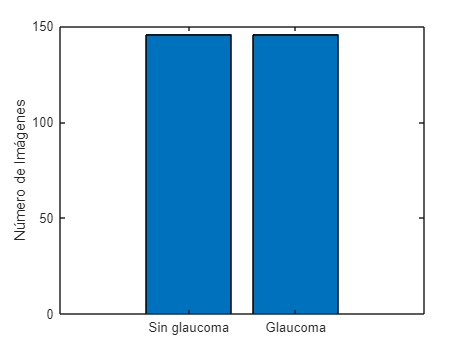


indices_buenas = find(T.glaucoma == 0);
indices_malas = find(T.glaucoma == 1);
rng('default'); % Para reproducibilidad
indices_buenas_seleccionadas = datasample(indices_buenas, num_malas, 'Replace', false);
indices_seleccionados = [indices_buenas_seleccionadas; indices_malas];

% Crear un nuevo conjunto de datos con el mismo número de imágenes en cada clase
T = T(indices_seleccionados, :);
num_buenas = sum(T.glaucoma==0);
num_malas = sum(T.glaucoma==1);

% Crear un vector con el número de imágenes para cada categoría
num_imagenes = [num_buenas, num_malas];

% Crear un gráfico de barras
figure;
bar(num_imagenes);
ylabel('Número de Imágenes');
xticklabels({'Sin glaucoma', 'Glaucoma'});


T.imagen=[];
% % T.NRR_area_ratio=[];
T.std_intensidad=[];
% T.dist1=[];
% T.dist2=[];
% T.dist3=[];
% T.dist4=[];
T.centro1=[];
T.centro2=[];
T.nitidez_borde=[];
T.nitidez_bordeG=[];
T.nitidez_bordeR=[];
T.nitidez_bordeB=[];
T.media = [];
T.media_r = [];
T.media_b = [];
T.media_g = [];
% T.radioC = [];
% T.radioD = [];
T.var_intensidadR=[];
T.var_intensidadG=[];
T.var_intensidadB=[];
T.entropiaR=[];
T.entropiaG=[];
T.entropiaB=[];
T.rango_dinamicoR=[];
T.rango_dinamicoG=[];
T.rango_dinamicoB=[];
% % T.entropia=[];
T.var_intensidad=[];
T.rango_dinamico=[];
% % T.DDLS=[];
% % T.CDR = [];
% 
% % T.energy_gray=[];
% % T.contrast_gray=[];
% % T.homogeneity_gray=[];
% T.correlation_gray=[];
% 
T.energy_red=[];
T.contrast_red=[];
T.homogeneity_red=[];
T.energy_blue=[];
T.contrast_blue=[];
T.homogeneity_blue=[];
T.energy_green=[];
T.contrast_green=[];
T.homogeneity_green=[];
T.entropy_red=[];
T.entropy_green=[];
T.entropy_blue=[];
T.contrast_gray=[];
T.homogeneity_gray=[];
T.correlation_red=[];
T.correlation_green=[];
T.correlation_blue=[];

T.average_dh_db3 = [];
T.average_dv_db3 = [];
T.average_dh_sym3 = [];
T.average_dv_sym3= [];
T.average_dh_bior33 = [];
T.average_dv_bior33 = [];
T.average_dh_bior35 = [];
T.average_dv_bior35= [];
T.average_dh_bior37 = [];
T.average_dv_bior37= [];
T.energy_db3 = [];
T.energy_sym3 = [];
T.energy_bior33 = [];
T.energy_bior35 = [];
T.energy_bior37 = [];

variables=T.Properties.VariableNames

variables = 1×13 cell array
    {'entropia'}    {'CDR'}    {'DDLS'}    {'dist1'}    {'dist2'}    {'dist3'}    {'dist4'}    {'radioD'}    {'radioC'}    {'correlation_gray'}    {'entropy_gray'}    {'energy_gray'}    {'glaucoma'}


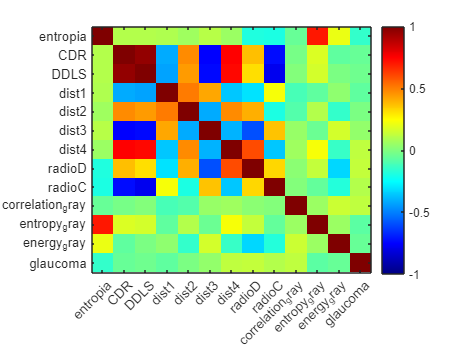


X = T{:, :};
R = corrcoef(X, 'Rows', 'pairwise'); % pairwise to ignore NaN values

figure;
imagesc(R); clim([-1 1]);
xticks(1:100);
xticklabels(variables(:));
yticks(1:100);
yticklabels(variables(:));
colormap(jet); colorbar;

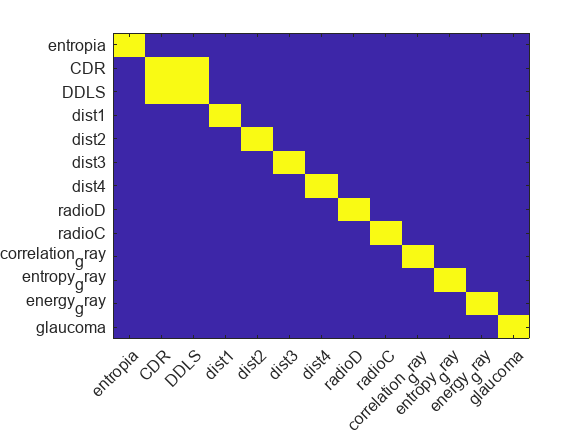


figure;
imagesc(abs(R)>0.95); clim([0 1]);
xticks(1:100);
xticklabels(variables(:));
yticks(1:100);
yticklabels(variables(:));

#### Preprocessing

[n, ~]=size(T);

T.glaucoma = cellstr(num2str(T.glaucoma)); %convertir quality en variable categorica
for i = 1:n
    if T.glaucoma{i} == '1'
        T.glaucoma{i} = 'Glaucoma';
    elseif T.glaucoma{i} == '0'
        T.glaucoma{i} = 'No Glaucoma';
    end
end

### 2. Data split

rng(6); 
p = 0.2;
cv_out = cvpartition(T.glaucoma, 'HoldOut', p, 'Stratify', true); 
% 20% -> pruebas
% 80% -> entrenar el modelo. 
% 'Stratify', true asegura que la distribución de clases se mantenga tanto en los conjuntos de entrenamiento como en los de prueba

T_train = T(cv_out.training, :); 
T_test  = T(cv_out.test, :);

k = 10; % técnica de validación cruzada de 10 pliegues
cv_in = cvpartition(T_train.glaucoma, 'KFold', k, 'Stratify', true);

%PONER Z-SCORE

### **3. Model training**

results = table;

#### **K-nearest neighbors (KNN)**

**con todas el mejor knn (neighbords 3)**

mdl_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 3, 'CVPartition', cv_in); % number of neighbors: 3
mdl_loss = kfoldLoss(mdl_knn); % mean error value

Y_pred = kfoldPredict(mdl_knn);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("knn", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Classification Trees**

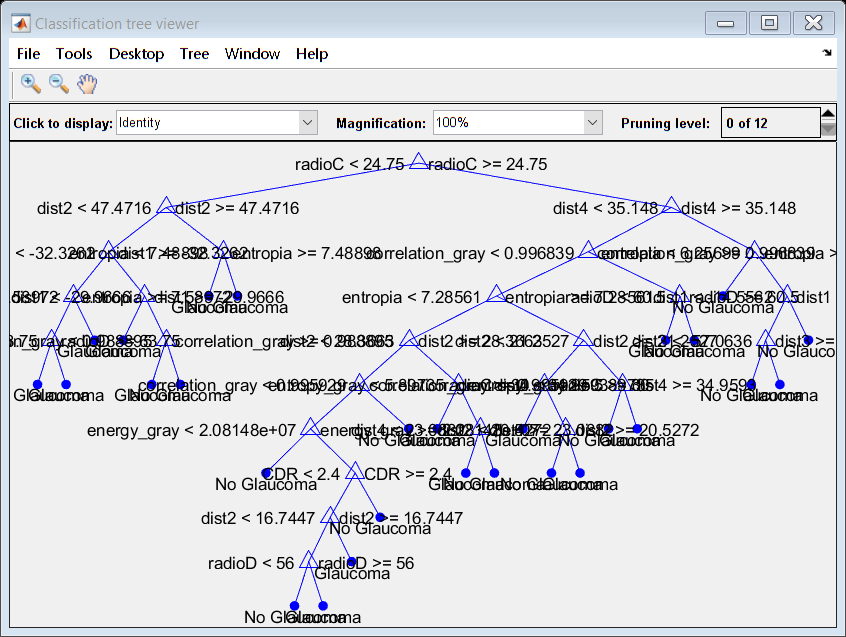

mdl_tree = fitctree(T_train, 'glaucoma', 'CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_tree);

Y_pred = kfoldPredict(mdl_tree);

accuracy = sum(strcmp(T_train.glaucoma, Y_pred)) / height(T_train);
results = [results; table("tree", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

first_fold_tree = mdl_tree.Trained{1};
view(first_fold_tree, 'Mode', 'graph');

#### Naive Bayes

mdl_NB = fitcnb(T_train, 'glaucoma','CVPartition', cv_in);
% mdl_loss = kfoldLoss(mdl_NB);

Y_pred = kfoldPredict(mdl_NB);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("naive_bayes", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### Discriminant Analysis

- **LDA**: asume que las matrices de covarianza de cada clase son iguales.

mdl_lda = fitcdiscr(T_train, 'glaucoma','CVPartition', cv_in);
mdl_loss = kfoldLoss(mdl_lda);
Y_pred = kfoldPredict(mdl_lda);
accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);

results = [results; table("LDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

- **QDA:** asume que las matrices de covarianza de cada clase son diferentes.

% mdl_qda = fitcdiscr(T_train, 'glaucoma','DiscrimType','quadratic','CVPartition',cv_in);
% mdl_loss = kfoldLoss(mdl_qda);
% 
% Y_pred = kfoldPredict(mdl_qda);
% 
% accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
% results = [results; table("QDA", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

#### **Support Vector Machines (SVM)**

mdl_svm = fitcecoc(T_train, 'glaucoma','CVPartition',cv_in);
mdl_loss = kfoldLoss(mdl_svm);

Y_pred = kfoldPredict(mdl_svm);

accuracy = sum(strcmp(Y_pred, T_train.glaucoma)) / height(T_train);
results = [results; table("SVM", mdl_loss, accuracy, 'VariableNames',{'model','loss','accuracy'})];

### 4. Model comparison

results

results = 5×3 table
        model         loss      accuracy
    _____________    _______    ________

    "knn"            0.49145    0.50855 
    "tree"           0.44444    0.55556 
    "naive_bayes"    0.44444    0.55128 
    "LDA"             0.4188     0.5812 
    "SVM"            0.47436    0.52564 


[~, best_model] = max(results.accuracy);
results(best_model, :) %balance accuracy

ans = 1×3 table
    model     loss     accuracy
    _____    ______    ________

    "LDA"    0.4188     0.5812 


### 5. Final model testing

mdl_final_SVM = fitcecoc(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_SVM, T_test);

loss_final2 = loss(mdl_final_SVM, T_test)

loss_final2 = 0.4828

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final2 = 0.5172

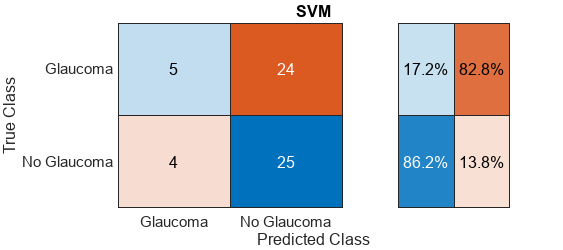


Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('SVM');


mdl_final_LDA = fitcdiscr(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_LDA, T_test);

loss_final2 = loss(mdl_final_LDA, T_test)

loss_final2 = 0.4138

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final2 = 0.5862

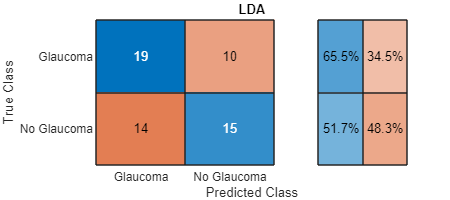


Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('LDA');

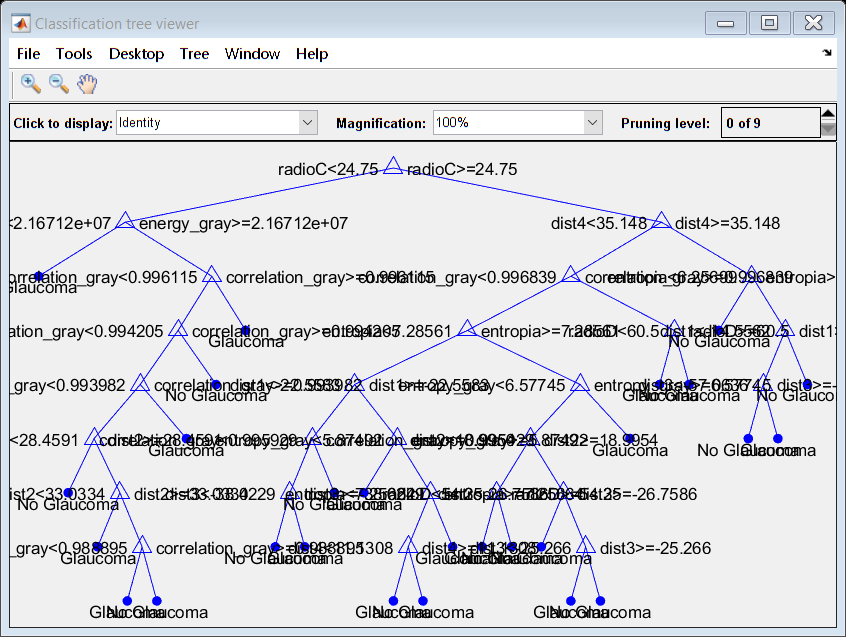


mdl_final_tree = fitctree(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_tree, T_test);
% 
% first_fold_tree = mdl_final_tree.view{1};
view(mdl_final_tree, 'Mode', 'graph');


loss_final2 = loss(mdl_final_tree, T_test)

loss_final2 = 0.3966

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final2 = 0.6034

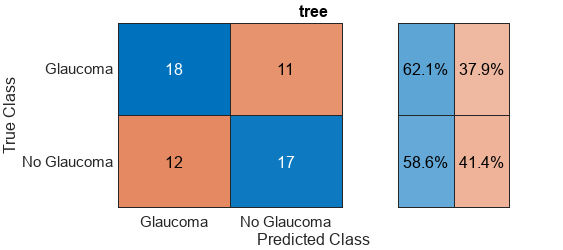


Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('tree');


mdl_final_knn = fitcknn(T_train, 'glaucoma', 'NumNeighbors', 6);
Y_pred2 = predict(mdl_final_knn, T_test);

loss_final2 = loss(mdl_final_knn, T_test)

loss_final2 = 0.4138

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final2 = 0.5862

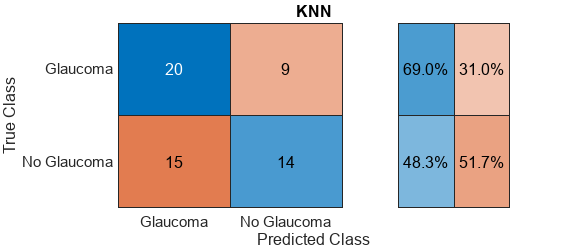


Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('KNN');


mdl_final_nb = fitcnb(T_train, 'glaucoma');
Y_pred2 = predict(mdl_final_nb, T_test);

loss_final2 = loss(mdl_final_nb, T_test)

loss_final2 = 0.4138

accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma)

accuracy_final2 = 0.5862

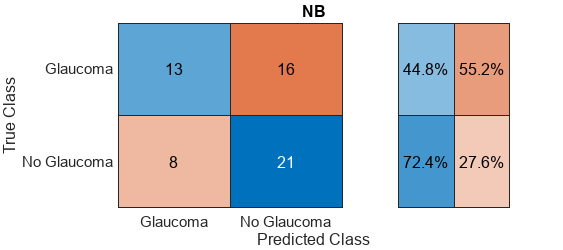


Y_test  = T.glaucoma(cv_out.test);

figure('Position', [0 0 450 200]);
confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('NB');


% mdl_final_QDA = fitcdiscr(T_train, 'glaucoma','DiscrimType','quadratic');
% Y_pred2 = predict(mdl_final_QDA, T_test);
% 
% loss_final2 = loss(mdl_final_QDA, T_test)
% accuracy_final2 = sum(strcmp(Y_pred2, T_test.glaucoma)) / height(T_test.glaucoma);
% 
% Y_test  = T.glaucoma(cv_out.test);
% 
% figure('Position', [0 0 450 200]);
% confusionchart(Y_test, Y_pred2, 'RowSummary','row-normalized'); title('QDA');

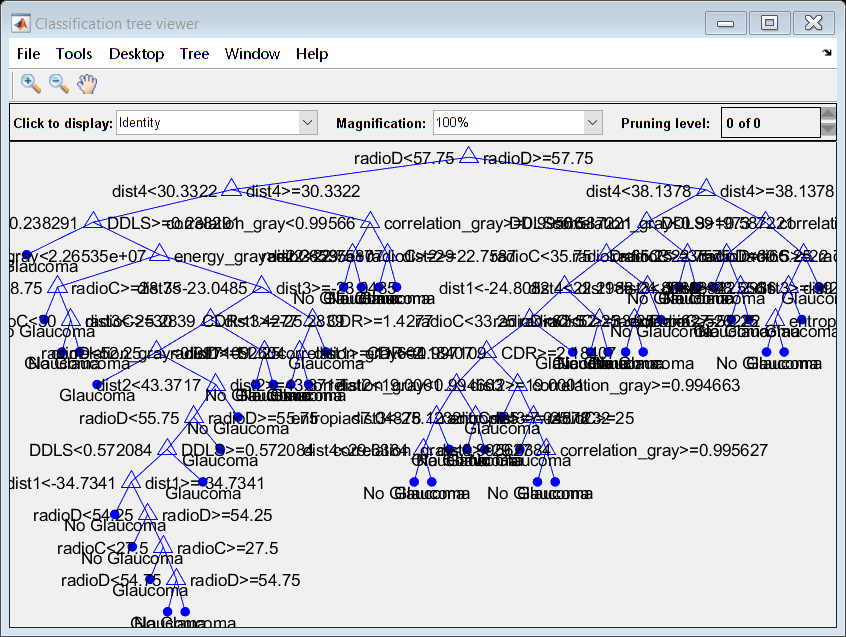

mdl_final_RF = TreeBagger(50, T_train, 'glaucoma', 'Method', 'classification');
Y_pred_RF = predict(mdl_final_RF, T_test);
% Pérdida (error) del modelo
% loss_RF = loss(mdl_final_RF, T_test);
first_fold_tree = mdl_final_RF.Trees{1};
view(first_fold_tree, 'Mode', 'graph');

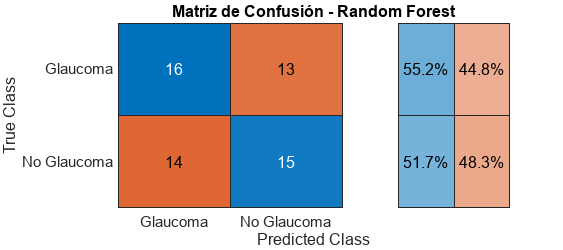


% Exactitud (accuracy) del modelo
accuracy_RF = sum(strcmp(Y_pred_RF, T_test.glaucoma)) / height(T_test.glaucoma);
figure('Position', [0 0 450 200]);
confusionchart(T_test.glaucoma, Y_pred_RF, 'RowSummary', 'row-normalized'); 
title('Matriz de Confusión - Random Forest');

% T = readtable("CaracteristicasDETECCION2.csv");
% 
% % Realiza las predicciones
% prediccion4 = predict(mdl_final_LDA, T);
% 
% % Convierte las predicciones a 0 y 1
% prediccion_numerica = strcmp(prediccion4, 'Glaucoma');
% 
% % Compara las predicciones numéricas con los valores reales de glaucoma en T
% es_correcto = (prediccion_numerica == T.glaucoma);
% 
% % Crea una nueva tabla que incluya las columnas imagen, glaucoma, prediccion y si la predicción fue correcta o no
% GLAUCOMA_PRED = table(T.imagen, T.glaucoma, prediccion4, es_correcto, 'VariableNames', {'imagen', 'glaucoma', 'prediccion', 'es_correcto'})
% num_correctas = sum(es_correcto)
